s0_add_paths

## Calculate the contrast energy

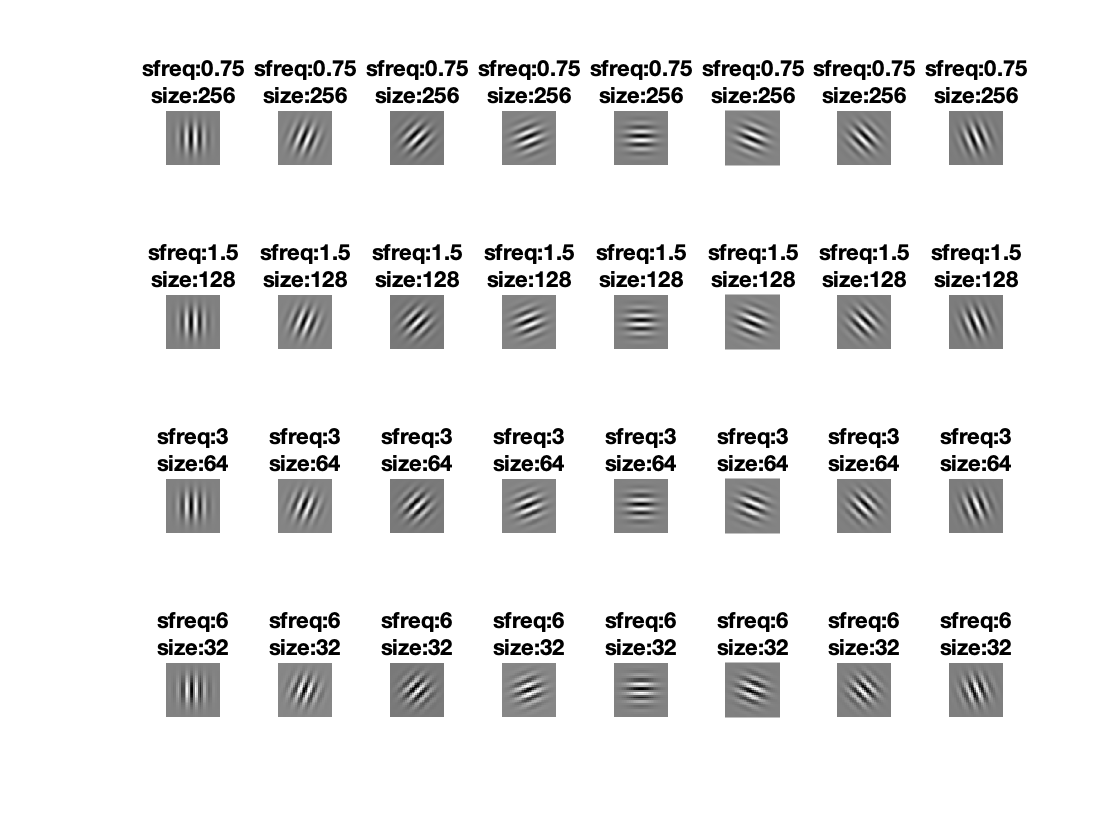

% load the original image
ds = 1; filter_cpd = [.75, 1.5, 3, 6];
fname = sprintf('stimuli-dataset%02d_orig.mat', ds);
path  = fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
% preprocess
stimuli  = double(stimuli);
stimuli  = stimuli./255 - .5;
labelVec = 1:size(stimuli, 4);
[Gabor_c, Gabor_s] = get_Filters(stimuli, ds, filter_cpd);
showFilters(Gabor_c, filter_cpd)

[E_ori, E_space] = cal_E(stimuli, ds, Gabor_c, Gabor_s);

## Calculate the contrast energy

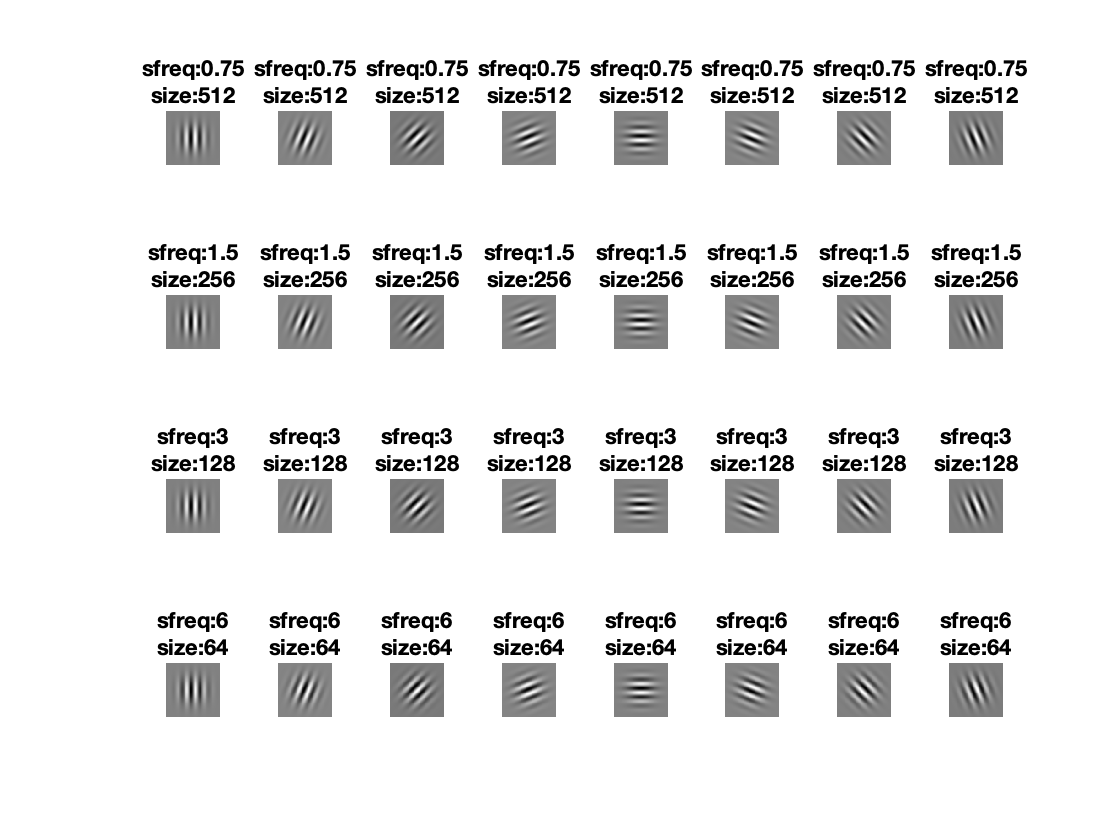

% load the original image
ds = 4; filter_cpd = [.75, 1.5, 3, 6];
fname = sprintf('stimuli-dataset%02d_orig.mat', ds);
path  = fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
% preprocess
stimuli  = double(stimuli);
stimuli  = stimuli./255 - .5;
labelVec = 1:size(stimuli, 4);
[Gabor_c, Gabor_s] = get_Filters(stimuli, ds, filter_cpd);
showFilters(Gabor_c, filter_cpd)

## Appendix: functions in the script

function showFilters(Gabor_c, filter_cpd)

% visualize
nR = size(Gabor_c, 2); nC = size(Gabor_c, 1);
for k= 1:1
    for j = 1:nR
        for i = 1:nC
            subplot(nR, nC, (j-1)*nC+i)
            sf = filter_cpd(j);
            imshow(Gabor_c{i, j}, []);
            img_size = size(Gabor_c{i, j},1);
            
            title(sprintf('sfreq:%01g\nsize:%d', sf, img_size))
        end
    end
end

end